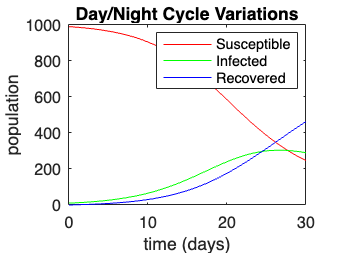

%Periodic Variation of Transmission Rate
A = 5;
omega = 2*pi;
h = 0.1;
b0 = 0.3;
gamma = 0.1;
T0 = 0;
T = 30;
S0 = 990;
I0 = 10;
R0 = 0;
DayNight = modelSIR_P4(S0,I0,R0,T0,T,h,b0,A,omega,gamma);


plot(DayNight(1,:),DayNight(2,:),'r',DayNight(1,:),DayNight(3,:),'g',DayNight(1,:),DayNight(4,:),'b');
xlabel('time (days)');
ylabel('population');
legend('Susceptible','Infected','Recovered');
title('Day/Night Cycle Variations');

f = omega/(2*pi)*(0:(T/2)/T);

fftSus = fft(DayNight(2,:));
fftSusabs = abs(fftSus/T);
P1 = fftSusabs(1:T/2+1);
P1(2:end-1) = 2*P1(2:end-1);

fftInf = fft(DayNight(3,:));
fftInfabs = abs(fftInf/T);
P3 = fftInfabs(1:T/2+1);
P3(2:end-1) = 2*P3(2:end-1);

fftRec = fft(DayNight(4,:));
fftRecabs = abs(fftRec/T);
P5 = fftRecabs(1:T/2+1);
P5(2:end-1) = 2*P5(2:end-1);
%Frequency = ?
plot(f,P1)
xlabel('f(Hz)');
ylabel('Fast Fourier Transform');
title('Magnitude of S Spectrum');
